clear all;

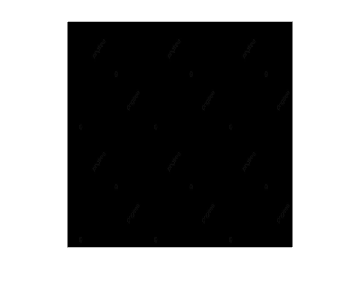

bild = imread('bild3.jpg');
imshow(imresize(bild, [300 300]))

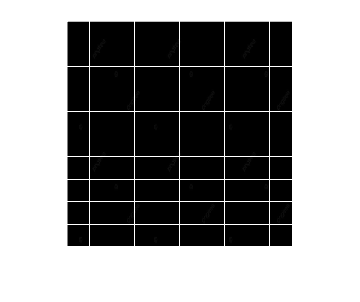

b = zeichenWeisseLinen(bild, 30);
imshow(b);

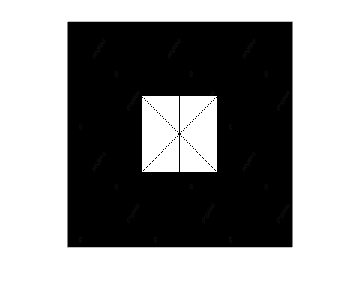

figure;
bErg = zeichneRechtEck(bild, 100);
imshow(bErg)

function [bildErg] = zeichenWeisseLinen(bild, linePunkt)
    bild = imresize(bild, [300 300]);
    [zeilen, spalten] = size(bild);
    bildErg  = bild;
    for i = 1:zeilen
        for j = 1: spalten
            if i*linePunkt <= zeilen
                bildErg(i*linePunkt, j) = 255;
            end
        end
    end

     for i = 1:zeilen
        for j = 1: spalten
            if j*linePunkt <= zeilen
                bildErg(i, j*linePunkt) = 255;
            end
        end
    end

end

function [bildErg] = zeichneRechtEck(bild, quadratGroesse)
    bild = imresize(bild, [300 300]);
    [zeilen, spalten] = size(bild);
    bildErg  = bild;
    for i = quadratGroesse:quadratGroesse:quadratGroesse*2
        for j = quadratGroesse:1:quadratGroesse*2
             bildErg(i, j) = 255;
        end
    end
    for i = quadratGroesse:quadratGroesse:quadratGroesse*2
       for j = quadratGroesse:1:quadratGroesse*2
             bildErg(j, i) = 255;
       end
    end
    for i = quadratGroesse:quadratGroesse*2
        for j = quadratGroesse:quadratGroesse*2
             bildErg(i, j) = 255;
        end
    end
    for i = quadratGroesse:quadratGroesse*2
        bildErg(i, i) = 0;
    end
    for i = 1:quadratGroesse
        bildErg(i+quadratGroesse, quadratGroesse*2-i) = 0;
    end
    for i = quadratGroesse:quadratGroesse*2
        bildErg(quadratGroesse/2 + quadratGroesse, i) = 0;
    end
     for i = quadratGroesse:quadratGroesse*2
        bildErg(i, quadratGroesse + quadratGroesse/2) = 0;
    end


end